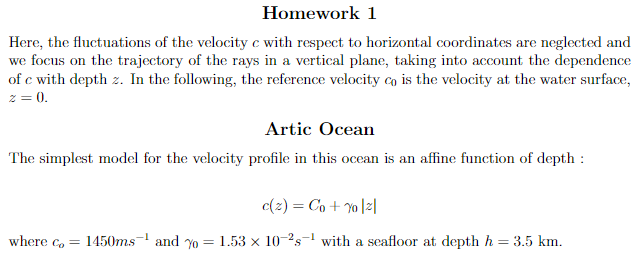

clear
clc

% Initial conditions
Co = 1450;
gamma = 1.53e-2;
h = 3500 ; % maximun depth

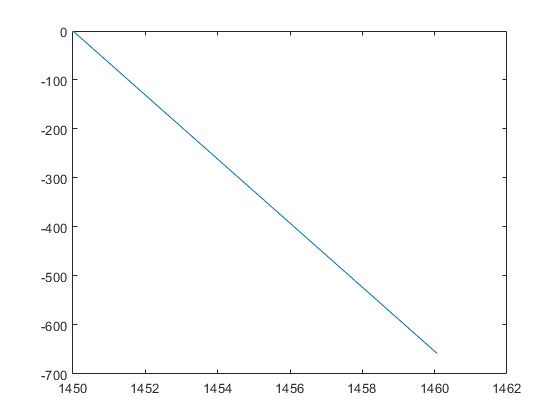

% Parameter difinition
zs = 600;
total_period = 30;
dt = 0.01;
t = 0:dt:total_period;


%theta = [-2:0.1:2];
x = zeros(size(t));
x(1) = 0;

z = zeros(size(t));
z(1) = zs;

theta = zeros(size(t));
theta(1)  = 2*pi/180;

c = zeros(size(t));
c(1)=velocity(z(1));


for i = 2:length(t)
    
    x(i) = x(i-1) + c(i-1) * dt * cos(theta(i-1));
    z(i) = z(i-1) + c(i-1) * dt * sin(theta(i-1));
    c(i) = velocity(z(i));
    
    % Snail constant
    K = cos(theta(i-1))*c(i)/c(i-1);
    
    if K <= 1
        
        theta(i) = sign(theta(i-1))*acos(K);
        
    else

        z(i) = z(i-1);
        c(i) = c(i-2);
        theta(i) = -theta(i-2);
        
    end
    

    if (z(i) <= 0) || (z(i)>=h)
        
        z(i) = z(i-1);
        c(i) = c(i-2);
        theta(i) = -theta(i-2);
        
    end   
    
end

plot(c,-z)

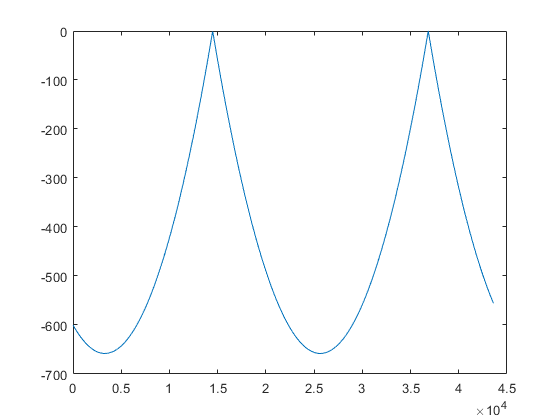

plot(x,-z)

function c = velocity(z)

    Co = 1450;
    gamma = 1.53e-2;
    
    c = Co + gamma*abs(z);
 
end